# ME5554/AOE5754/ECE5754 Applied Linear Systems - Final Project

Name: Mohitha Mikkilineni                     Submission Date: 11/12/2020

clear, clc
format short g
format compact

## **Problem 1a. **

**Reason:**

To design a a full state feedback gain matrix using LQR function:

$(i)$ Assume that the drone starts out with zero velocities  and given the initial positions as

$x(0) = -2 $m, $ y(0) = 1$m, $ \theta(0) = -0.5 rad$

$(ii)$ Select a state weighting matrix $Q$ and an actuator weighting matrix $R$ such that it satisfies the control objectives:

      We know that we have to choose both $Q$ and $R$ such that both weighting matrices are square, real, symmetric and positive definite.

      The common simplification is to choose

       $Q=qC^TC$ and $R=rI$

     This can be further simplified by rewriting the integrand as:

      Moreover, we know that varying the weighting matrices $Q$ and $R$ allows us to trade off the “size” of the state response with the “size” of the control effort.

       $a)$When $|Q| << |R|$, then the cost function will minimize the amount of control effort needed (gains will be small).

        $b)$When $ |R| << |Q|$, then the cost function will minimize the state response without regard to the amount of control effort that we need (gains will be large).

#### Design Requirements:

Tuning the LQR weights to achieve the following requirements:

• Simulate the closed-loop initial value response out to 6 seconds

 $\Rightarrow $ Tfinal= 6 seconds

• Each of the 5% settling times on the outputs must be less than 6 seconds 

  
$$\Rightarrow T_{s} < 6$$


• Drive all six states, and therefore all three outputs to zero 

• Both of the control signals must be within the maximum limits 

      $u_{1}< u_{1_{max}}$     and $u_{2}<u_{2_{max}$

• The absolute value of the pitch angle can never exceed the absolute value of the initial pitch angle during the entire simulation

            
$$ |\theta{(t)}| \le  |\theta(0)|$$


• The final LQR solution is allowed to let the drone position be below ground level (y<0) during the simulation and must end at (or near) y=0.

- 
$$y(t) \ge 0$$


% Problem 0 and  1a. 
% Problem 0
% Loading open-loop state-space LTI model from the Midterm Project in a
% .mat file: "Open-loop_LTI"
 load('C:\Users\aswin\Desktop\ALS_FP\Openloop_LTI.mat','ol_sys');
 
% Problem 1
%Open loop LTI system:
A_ol_sys = ol_sys.A; 
B_ol_sys = ol_sys.B; 
C_ol_sys = ol_sys.C; 
D_ol_sys = ol_sys.D;

%Given initial positions
x_0=-2;
y_0=1;
theta_0=-0.5;

% Initial condition for State Variables
p_0 = 0;          % m/s
q_0 = 0;          % m/s
r_0 = -0.5;           % rad
s_0= 0;             %rad/s
v_0=-2;              %m
w_0=1;               %m

State_Vector_0 = [p_0; q_0; r_0; s_0;v_0;w_0];

% Using trial and error approach to find Q and R:
% Choose Q and R such that 
% We know that Q and R are diagonal matrixes
% 5% Settling time of all three outputs must be less than 6 second.
% u_1 < u_1_max and u_2<u_2_max
% |theta(t)|< |theta(0)|
scenario = 1;   

switch scenario
    case 1
       
        Q= diag([0.1*1e6 0.1*1e6 19*1e6 0.1*1e6 7.9*1e6 3.1*1e6]);
        R= diag([4.5 3.1]);
        

    case 2
        Q = diag([19*1e6 20*1e6 1*1e6 11*1e6 51*1e6 25*1e6 ]); 
        R = diag([1.5 0.01]);
        
    case 3
        Q = diag([1.9*1e6 25*1e6 1.1*1e6 19.1*1e6 5.2*1e6 0.27*1e6 ]); 
        R = diag([3.5 6.01]);
        
    otherwise
        error('Unknown method')
end
%LQR Function
[K_lqr, S_lqr, E_lqr] = lqr(ol_sys,Q,R);

disp('K computed via LQR:')

K computed via LQR:


disp(K_lqr)

       113.13       151.19       2032.9      -546.42      -1019.1        530.4
       164.06      -151.32      -2034.8       546.95       1020.1       769.17


## **Problem 1b:**

Construct a closed-loop LTI state-space model. You may find it helpful to

generate a table of the closed-loop poles, the natural frequencies and the damping ratios to check your

work. Use the INITIAL function in Matlab to simulate the initial value response for the closed-loop

system using the LQR optimal control gains from Problem 1a. Use your plot code from the Midterm

Project to display your closed-loop time-series results in a single figure window. All axes must be

properly annotated and the plots must match the format from the Midterm Project. Note that Problem

1a is the design part and Problem 1b is the simulation part of the same problem, so you will need to

iterate both of these together to generate your solution.

**Simulation:**


% Problem 1b.

A_cl_sys = A_ol_sys - B_ol_sys*K_lqr;       %Matrix A for closed-loop system
cl_sys = ss(A_cl_sys, B_ol_sys, C_ol_sys, D_ol_sys); %Closed-loop LTI model


% Using function 'damp' to compute poles, natural frequency and damping
% ratio
[wn_cl, zeta_cl, P_cl] = damp(cl_sys);
damp(cl_sys) %Displayed poles are in increasing order

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.83e+00 + 1.73e+00i     7.28e-01       2.52e+00         5.46e-01    
 -1.83e+00 - 1.73e+00i     7.28e-01       2.52e+00         5.46e-01    
 -5.97e+00                 1.00e+00       5.97e+00         1.67e-01    
 -1.45e+01                 1.00e+00       1.45e+01         6.89e-02    
 -1.47e+01                 1.00e+00       1.47e+01         6.81e-02    
 -3.94e+01                 1.00e+00       3.94e+01         2.54e-02    


Wn_cl = wn_cl/(2*pi);  %converting natural frequencies(rad/sec) to Hz
tau_cl=1./(wn_cl.*zeta_cl); %Time Constant

fprintf(' The Closed-loop eigen values(poles(P)),damping ratios(Z), natural frequencies(Wn) and time constants are: ');

 The Closed-loop eigen values(poles(P)),damping ratios(Z), natural frequencies(Wn) and time constants are: 

T = table(P_cl, zeta_cl, Wn_cl, abs(tau_cl));
T.Properties.VariableNames = {'EigenValues or Poles', 'DampingRatios','NaturalFrequencies (Hz)','TimeConstants (seconds)'};
disp(T);

    EigenValues or Poles    DampingRatios    NaturalFrequencies (Hz)    TimeConstants (seconds)
    ____________________    _____________    _______________________    _______________________
      -1.8305+1.7263i          0.7275                0.40046                     0.5463        
      -1.8305-1.7263i          0.7275                0.40046                     0.5463        
      -5.9719+0i                    1                0.95046                    0.16745        
      -14.508+0i                    1                  2.309                   0.068929        
      -14.686+0i                    1                 2.3373                   0.068093        
      -39.444+0i                    1                 6.2777                   0.025353        


Tfinal=6 ;      %Final time
%Compute the Initial Value response
[Y,T,X] = initial(cl_sys, State_Vector_0, Tfinal);

Y_Output = lsiminfo(Y,T,'SettlingTime',0.05);

% Converting LSIMINFO structure to a table for display purposes
YTable = struct2table(Y_Output); 

% Horizontal Position (m) of the CG in the world coordinate system at 5% Settling time, 
HorizontalPosition_SettlingTime = interp1(T(:,1),Y(:,1),YTable.SettlingTime(1));
disp(' Horizontal Position (x) at 5% Settling time: ');

 Horizontal Position (x) at 5% Settling time: 


fprintf('Time = %.4f s, HorizontalPosition(x) = %.4f m', YTable.SettlingTime(1), HorizontalPosition_SettlingTime);

Time = 1.2630 s, HorizontalPosition(x) = -0.0999 m

% Vertical Position (m) of the CG in the world coordinate system at 5% Settling time,
VerticalPosition_SettlingTime = interp1(T(:,1),Y(:,2),YTable.SettlingTime(2));
disp(' VerticalPosition (y) at 5% Settling time: ');

 VerticalPosition (y) at 5% Settling time: 


fprintf('Time = %.4f s, VerticalPosition (y) = %.4f m', YTable.SettlingTime(2), VerticalPosition_SettlingTime);

Time = 0.5900 s, VerticalPosition (y) = 0.0500 m


% Angular position (rad) of the open-top bin at 5% Settling time
AngularPosition_SettlingTime = interp1(T(:,1),Y(:,3),YTable.SettlingTime(3));
disp('Angular position (theta) at 5% Settling time: ');

Angular position (theta) at 5% Settling time: 


fprintf('Time = %.4f s, AngularPosition(theta) = %.4f rad', YTable.SettlingTime(3), AngularPosition_SettlingTime);

Time = 1.9174 s, AngularPosition(theta) = 0.0410 rad


ControlInput = abs(K_lqr*X');
controlPeak1 = max(max(ControlInput(1,:)));
controlPeak2 = max(max(ControlInput(2,:)));
fprintf('  Peak absolute variational control signal (u_1) is: %6.f N ', controlPeak1);

  Peak absolute variational control signal (u_1) is:   1552 N 

fprintf('  Peak absolute variational control signal (u_2) is: %6.f N ', controlPeak2);

  Peak absolute variational control signal (u_2) is:    408 N 


fprintf('\n \n \n \n');

% Plot control signals and outputs  
figure();
% Closed-Loop Output Response with initial values (Horizontal Position (x))
subplot(3,2,1);
plot(T,Y(:,1));
grid on
hold on
xlim([0 6])
title(['Closed-Loop Output Response with initial values (Horizontal Position (x))']);
xlabel('Time (seconds)')
ylabel('x (meters)')
plot(YTable.SettlingTime(1),HorizontalPosition_SettlingTime,'kO');
text(YTable.SettlingTime(1), HorizontalPosition_SettlingTime,['(' num2str(YTable.SettlingTime(1)) ',' num2str(HorizontalPosition_SettlingTime) ')']);
legend('Horizontal Position (x) in m', '5% Settling time Coordinates', '');


%Closed-Loop Output Response with initial values (Vertical Position (y))
subplot(3,2,3);
plot(T,Y(:,2),'r');
grid on
hold on
xlim([0 6])
title(['Closed-Loop Output Response with initial values (Vertical Position (y))']);
xlabel('Time (seconds)')
ylabel('y (meters)')
plot(YTable.SettlingTime(2), VerticalPosition_SettlingTime,'kO');
text(YTable.SettlingTime(2),VerticalPosition_SettlingTime,['(' num2str(YTable.SettlingTime(2)) ',' num2str(VerticalPosition_SettlingTime) ')']);
legend('Vertical Position (y) in m', '5% Settling time Coordinates', '');


%Closed-Loop Output Response with initial values ( Angular Position (theta))
subplot(3,2,5);
plot(T,Y(:,3),'b');
grid on
hold on
title(['Closed-Loop Output Response with initial values ( Angular Position (theta))']);
xlabel('Time (seconds)')
ylabel('theta (radians)')
xlim([0 6])
plot(YTable.SettlingTime(3),AngularPosition_SettlingTime,'kO');
text(YTable.SettlingTime(3),AngularPosition_SettlingTime ,['(' num2str(YTable.SettlingTime(3)) ',' num2str(AngularPosition_SettlingTime) ')']);
legend('Angular Position (theta) in rad','5% Settling time Coordinates', '');

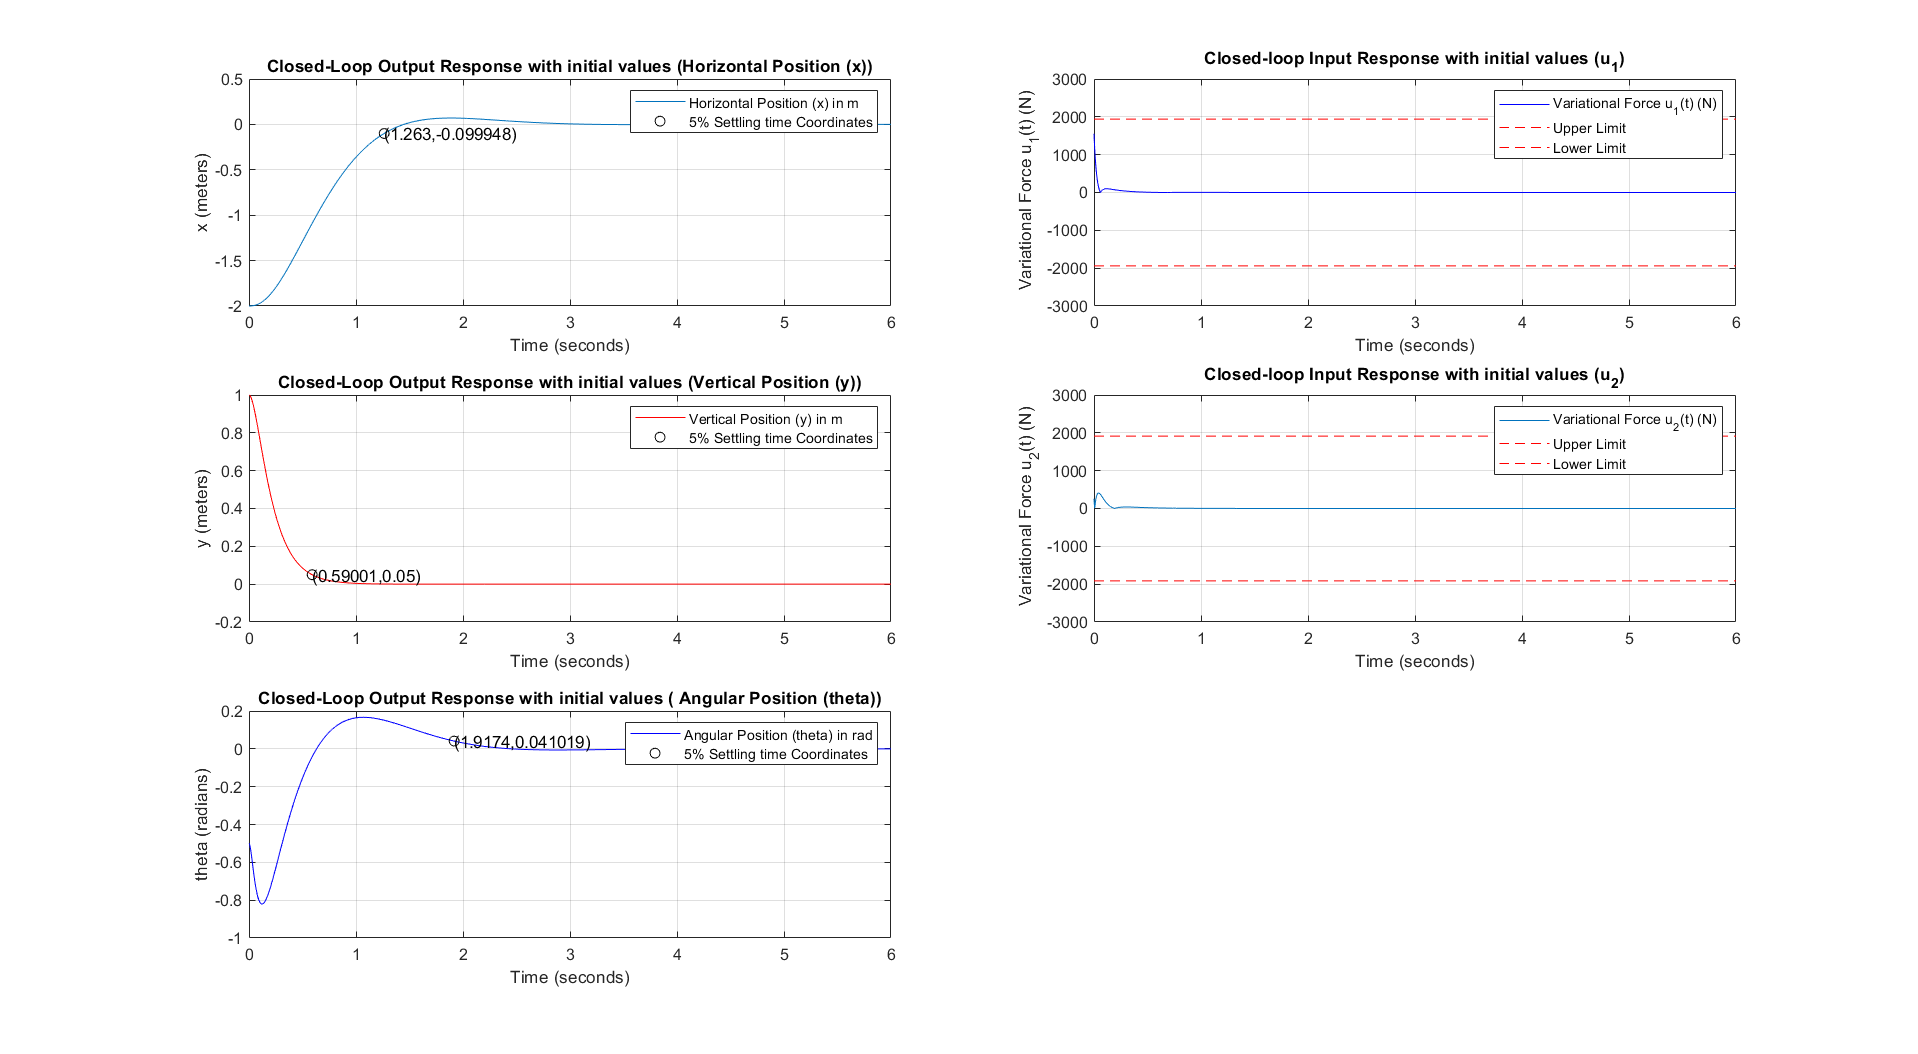


%Closed-loop Input Response with initial values (u_1)
subplot(3,2,2); 
plot(T,ControlInput(1,:),'b');
grid on
hold on
hRl=refline(0,1939.936);
set(hRl,'color','r','linestyle','--'); 
hR2=refline(0,-1939.936);
set(hR2,'color','r','linestyle','--'); 
title('Closed-loop Input Response with initial values (u_1)');
xlabel('Time (seconds)')
ylabel(' Variational Force u_1(t) (N)')
ylim([-3e3 3e3])
xlim([0 6])
legend('Variational Force u_1(t) (N)','Upper Limit','Lower Limit');

%Closed-loop Input Response with initial values (u_2)
subplot(3,2,4);

plot(T,ControlInput(2,:))
grid on
hold on
hRefl=refline(0,1912.914);
set(hRefl,'color','r','linestyle','--'); 
hRef2=refline(0,-1912.914);
set(hRef2,'color','r','linestyle','--'); 
title('Closed-loop Input Response with initial values (u_2)');
xlabel('Time (seconds)')
ylabel(' Variational Force u_2(t) (N)')
ylim([-3e3 3e3])
xlim([0 6])
legend('Variational Force u_2(t) (N)','Upper Limit','Lower Limit');
set(gcf, 'Units', 'Normalized', 'Position', [1, 1, 1, 1]);


warning('off')


## **Problem 2. **

Show that the open-loop plant is Completely Observable. Also determine and

document which subsets of outputs results in a Completely Observable system

**Reason:**

To show that the open-loop plant is Completely Observable. 

The poles of an observer can be placed arbitrarily iff the system is observable or the observability matrix has full rank.

 rank(O)=N


$$O=[ C^T A^TC^T A^{T^2}C^T  A^{T^3}C^T .....A^{T^{N-1}}C^T]$$


Here, N = 6, and thus O martrix is full rank iff rank(O) = 6

% Problem 2.

O = obsv(A_ol_sys,C_ol_sys); % Observability matrix 
O_rank = rank(O);

fprintf(' The rank of the observability matrix "O" is: ');

 The rank of the observability matrix "O" is: 

disp(O_rank);

     6


if O_rank == 6
    fprintf(' The open-loop plant is completely observable ');
end

 The open-loop plant is completely observable 

To determine and document which subsets of outputs results in a Completely Observable system.

We need to check the observerability by feeding the components of output matrix.

We can see that when both outputs 1 and 2 are fed into the system, the system is completely observable. In rest all other cases, the system is not completely observable.

%To determine and document which subsets of outputs results in a Completely Observable system.

%C_OL with subset 1 (with only Y1 row)
C_output_subset1= C_ol_sys;
C_output_subset1(2,:)= zeros(6,1);
C_output_subset1(3,:)= zeros(6,1);
O_output_subset1 = obsv(A_ol_sys, C_output_subset1);
O_output_subset1_rank= rank(O_output_subset1);
fprintf(' The rank of the observability matrix with subset of output 1 is: ');

 The rank of the observability matrix with subset of output 1 is: 

disp(O_output_subset1_rank);

     4



%C_OL with subset 2 of output(with only Y2 row)
C_output_subset2= C_ol_sys;
C_output_subset2(1,:)= zeros(6,1);
C_output_subset2(3,:)= zeros(6,1);
O_output_subset2 = obsv(A_ol_sys, C_output_subset2);

O_output_subset2_rank= rank(O_output_subset2);
fprintf(' The rank of the observability matrix with subset of output 2 is: ');

 The rank of the observability matrix with subset of output 2 is: 

disp(O_output_subset2_rank);

     2



%C_OL with subset 3 of output(with only Y3 row)
C_output_subset3= C_ol_sys;
C_output_subset3(1,:)= zeros(6,1);
C_output_subset3(2,:)= zeros(6,1);
O_output_subset3 = obsv(A_ol_sys, C_output_subset3);
O_output_subset3_rank= rank(O_output_subset3);
fprintf(' The rank of the observability matrix with subset of output 3 is: ');

 The rank of the observability matrix with subset of output 3 is: 

disp(O_output_subset3_rank);

     2



 %C_OL with subset 1 and 2 of output(with Y1 AND Y2 rows)
C_output_subset_1and2= C_ol_sys;
C_output_subset_1and2(3,:)= zeros(6,1);
O_output_subset_1and2= obsv(A_ol_sys, C_output_subset_1and2);
O_output_subset_1and2_rank= rank(O_output_subset_1and2);
fprintf(' The rank of the observability matrix with subset of output 1 and 2 is: ');

 The rank of the observability matrix with subset of output 1 and 2 is: 

disp(O_output_subset_1and2_rank);

     6



 %C_OL with subset 1 and 3 of output(with Y1 AND Y2 rows)
C_output_subset_1and3= C_ol_sys;
C_output_subset_1and3(2,:)= zeros(6,1);
O_output_subset_1and3= obsv(A_ol_sys, C_output_subset_1and3);
O_output_subset_1and3_rank= rank(O_output_subset_1and3);
fprintf(' The rank of the observability matrix with subset of output 1 and 3 is: ');

 The rank of the observability matrix with subset of output 1 and 3 is: 

disp(O_output_subset_1and3_rank);

     4


 %C_OL with subset 2 and 3 of output(with Y1 AND Y2 rows)
C_output_subset_2and3= C_ol_sys;
C_output_subset_2and3(1,:)= zeros(6,1);
O_output_subset_2and3= obsv(A_ol_sys, C_output_subset_2and3);
O_output_subset_2and3_rank= rank(O_output_subset_2and3);
fprintf(' The rank of the observability matrix with subset of output 2 and 3 is: ');

 The rank of the observability matrix with subset of output 2 and 3 is: 

disp(O_output_subset_2and3_rank);

     4


## Problem 3a. 

Design a Luenberger observer such that an output feedback control system

using the LQR state feedback gains from problem 1 above meets the performance requirements from

1a when the closed-loop system is simulated for 6 seconds using the same initial condition vector in 1a.

Note: You must complete 3b to determine if your observer design for 3a meets the requirements!

On one figure, use unique markers to generate a plot of the open-loop poles, the closed-loop LQR

state-feedback poles, and the observer poles on a pole diagram (real vs. imag). Use the SGRID

function to augment your plot with lines of constant damping and lines of constant frequency. You must

also use the AXIS EQUAL command to insure that the aspect ratio is correct between the real and

imaginary axes. Properly annotate each axes with clearly defined axis labels, and legends

### Design:

####                                                                                                          Block diagram of a Luenberger Observer

                                                                                                    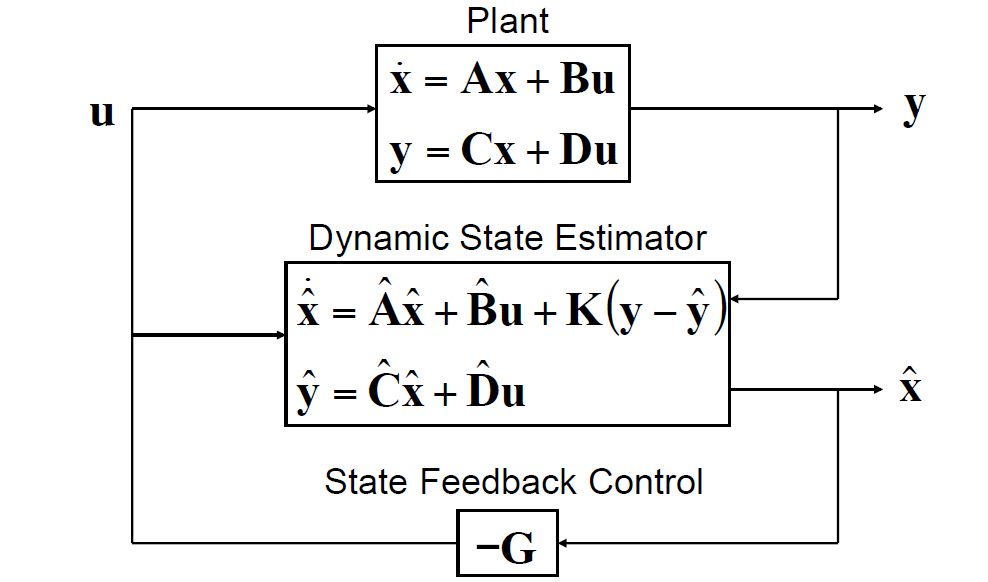

 The state estimation error dynamics for the Luenberger observer:

                             
$$\dot{e}= (Ax -\hat{A} \hat{x} )-K(Cx - \hat{C} \hat{x} )+ (B-\hat{B}) u -K(D-\hat{D} ) u$$


#### Requirements:

using the LQR weights to achieve the following requirements:

• Simulate the closed-loop initial value response out to 6 seconds

 $\Rightarrow $ Tfinal= 6 seconds

• Each of the 5% settling times on the outputs must be less than 6 seconds 

  
$$\Rightarrow T_{s} < 6$$


• Drive all six states, and therefore all three outputs to zero 

• Both of the control signals must be within the maximum limits 

      $u_{1}< u_{1_{max}}$     and $u_{2}<u_{2_{max}$

• The absolute value of the pitch angle can never exceed the absolute value of the initial pitch angle during the entire simulation

            
$$ |\theta{(t)}| \le  |\theta(0)|$$


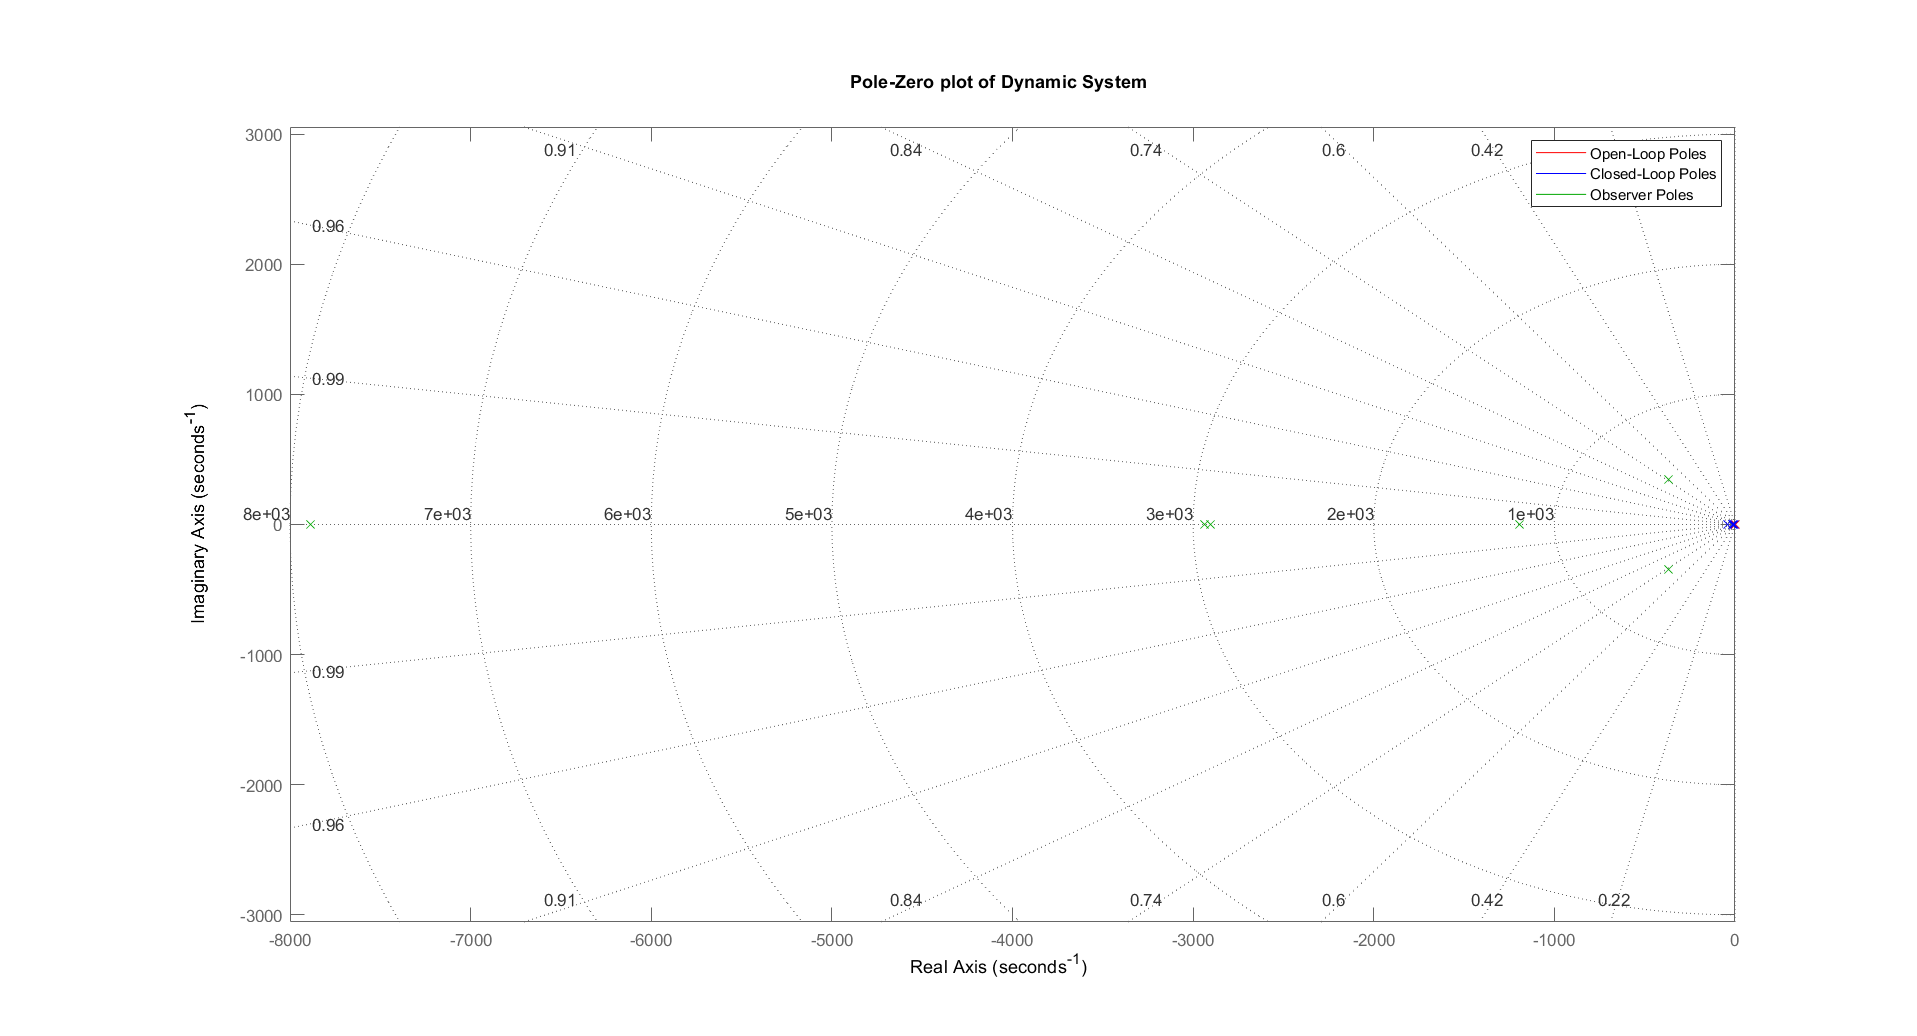

% Problem 3a.

%Designing a Luenberger observer such that an output feedback control system
A_obsv_cl_sys = A_cl_sys; 
A_obsv = A_ol_sys; 
B_obsv = B_ol_sys;
C_obsv = C_ol_sys;
D_obsv = D_ol_sys;


%Here the pair (A,C) is completely observable, hence the dual system (A',C',B',D') is completely reachable
%Then we can design a compensator K for the dual system and place the eigenvalues of (A' + C'K) arbitrarily
%The eigenvalues of matrix (A' + C'K) = eigenvalues of its transpose (A + K'C)

% We need to find the desired observer eigen values for the closed loop system.
% We have already displayed the closed-loop poles 

[wn_cl_sys, zeta_cl_sys, P_cl_sys] = damp(cl_sys); %Display closed loop poles

%We can move the poles left by increasing the gain factor 

%Desired observer eigen values
P_obsv = 200*P_cl_sys; 


% To Build the  observer:
% We first find its gain matrix K, and then create a state space model using (A-KC,B,C,D) 
K_obsv = place(A_obsv_cl_sys', C_obsv', P_obsv)';
obsv_sys= ss(A_obsv_cl_sys - K_obsv*C_obsv, B_obsv, C_obsv, D_obsv);  
Tfinal=6;      %Final time

%the open-loop pole on a pole diagram (real vs. imag)

[wn_ol_sys, zeta_ol_sys, P_ol_sys] = damp(ol_sys);
P_ol_sys_real=real(P_ol_sys); %real 
P_ol_sys_imag= imag(P_ol_sys); %imaginary 

%the closed-loop LQR state-feedback poles(real vs. imag)

[wn_cl_sys, zeta_cl_sys, P_cl_sys] = damp(cl_sys);
P_cl_sys_real=real(P_cl_sys); %real 
P_cl_sys_imag= imag(P_cl_sys); %imaginary 

%the observer poles on a pole diagram (real vs. imag)
P_obsv_real=real(P_obsv);%real 
P_obsv_imag=imag(P_obsv);%imaginary

% Pole diagram
figure()

%Open-loop Pole-zero plot of of dynamic system 
pzmap(ol_sys, 'r') 
hold on

%Closed-loop Pole-zero plot of of dynamic system 
pzmap(cl_sys, 'b') 
hold on

% Observer Pole-zero plot of of dynamic system 
pzmap(obsv_sys, 'g') 
hold on

sgrid
axis equal

legend('Open-Loop Poles', 'Closed-Loop Poles', 'Observer Poles');

set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
title('Pole-Zero plot of Dynamic System');

## Problem 3b.

**Reason:**

To simulate the complete output feedback controller using LQR state-feedback control gains and Luenberger observer feedback gains.

Stage 1:

This stage LTI model includes an augmented system(open loop plant and observer)

The augmented state-space system:

            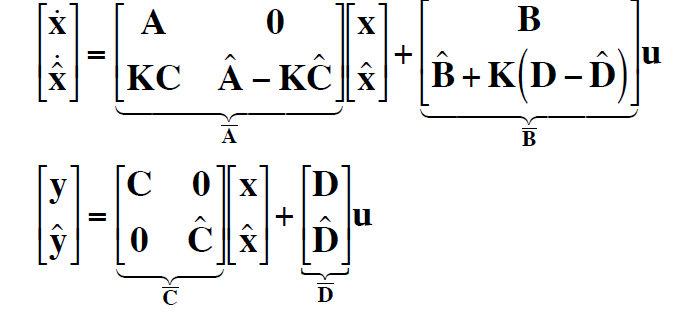

Stage 2:

This stage LTI model includes an augmented system(open loop plant, observer and state feedback control).

the augmented system dynamics are

             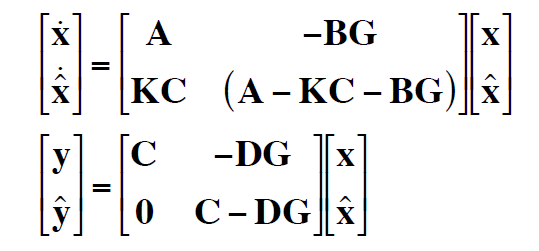

Initial Conditions:

$(i)$ Assume that the drone starts out with zero velocities  and given the initial positions as

$x(0) = -2 $m, $ y(0) = 1$m, $ \theta(0) = -0.5 rad$

$(ii)$Assume all the initial observer states as zero

$(iii)
$The duration of the first stage simulation must be 0.2 seconds. At t=0.2 seconds, the second stage simulation begins and this is where the controller is turned on (using

the second stage LTI model).

% Problem 3b.

%Stage 1:
%This stage LTI model includes an augmented system(open loop plant and observer)

% Assume all initial observer states as 0
State_Vector_obsv_0 = [ State_Vector_0; 0; 0; 0; 0; 0; 0];
G=K_lqr; % Gain for state feedback matrix

A_bar_ol_sys = [A_ol_sys,            -B_ol_sys*0*G;   K_obsv*C_ol_sys,     (A_ol_sys - K_obsv*C_ol_sys - B_ol_sys*0*G)];

B_bar_ol_sys = [B_ol_sys; (B_obsv + K_obsv*(D_ol_sys - D_obsv))];        
       
C_bar_ol_sys = [C_ol_sys, -D_ol_sys*0*G; zeros(3,6), (C_ol_sys - D_ol_sys*0*G)];                  

D_bar_ol_sys = [D_ol_sys; D_obsv];



% The augmented state-space system:
sys_stage1 = ss(A_bar_ol_sys, B_bar_ol_sys, C_bar_ol_sys, D_bar_ol_sys);


%The duration of the first stage simulation must be 0.2 seconds
Tfinal_stage1 = 0.2;

[Y_Stage1,T_Stage1,X_Stage1] = initial(sys_stage1, State_Vector_obsv_0, Tfinal_stage1); 


Y_Output1 = lsiminfo(Y_Stage1,T_Stage1,'SettlingTime',0.05);
%Conversion
 
YTab1 = struct2table(Y_Output1); 

% Horizontal Position (m) of the CG in the world coordinate system at 5% Settling time, 
HorizontalPosition_SettlingTime1 = interp1(T_Stage1(:,1),Y_Stage1(:,1),YTab1.SettlingTime(1));
disp(' Horizontal Position (x) at 5% Settling time: ');

 Horizontal Position (x) at 5% Settling time: 


fprintf('Time = %.4f s, HorizontalPosition(x) = %.4f m', YTab1.SettlingTime(1), HorizontalPosition_SettlingTime1);

Time = 0.1948 s, HorizontalPosition(x) = -1.9108 m

% Vertical Position (m) of the CG in the world coordinate system at 5% Settling time,
VerticalPosition_SettlingTime1 = interp1(T_Stage1(:,1),Y_Stage1(:,2),YTab1.SettlingTime(2));
disp(' VerticalPosition (y) at 5% Settling time: ');

 VerticalPosition (y) at 5% Settling time: 


fprintf('Time = %.4f s, VerticalPosition (y) = %.4f m', YTab1.SettlingTime(2), VerticalPosition_SettlingTime1);

Time = 0.0000 s, VerticalPosition (y) = 1.0000 m


% Angular position (rad) of the open-top bin at 5% Settling time
AngularPosition_SettlingTime1 = interp1(T_Stage1(:,1),Y_Stage1(:,3),YTab1.SettlingTime(3));
disp('Angular position (theta) at 5% Settling time: ');

Angular position (theta) at 5% Settling time: 


fprintf('Time = %.4f s, AngularPosition(theta) = %.4f rad', YTab1.SettlingTime(3), AngularPosition_SettlingTime1);

Time = 0.0000 s, AngularPosition(theta) = -0.5000 rad


%%Stage 2:
%This stage LTI model includes an augmented system(open loop plant and observer)

%the final state x at the end of the stage 1 simulation as the initial state vector for 
% the second stage simulation!
   


A_bar_stage2 = [A_ol_sys,  -B_ol_sys*G;   K_obsv*C_ol_sys,     (A_ol_sys - K_obsv*C_ol_sys - B_ol_sys*G)];

B_bar_stage2 = [];               
       
C_bar_stage2 = [C_ol_sys, -D_ol_sys*G; zeros(3,6), (C_ol_sys - D_ol_sys*G)];                   %

D_bar_stage2 = []; 
% The augmented state-space system:
sys_stage2 = ss(A_bar_stage2, B_bar_stage2, C_bar_stage2, D_bar_stage2);
State_Vector_obsv_0_Stage2 = X_Stage1(length(X_Stage1),:) ;

Tfinal_Stage2=5.8; %Simulation time

[Y_Stage2,T_Stage2,X_Stage2] = initial(sys_stage2, State_Vector_obsv_0_Stage2, Tfinal_Stage2);


% We know that the default settling time of LSIMINFO is 2%, so, we need to
% change it to 5% for both state responses (X) and the output Responses (Y)
% as mentioned

Y_Output2 = lsiminfo(Y_Stage2,T_Stage2,'SettlingTime',0.05);



YTab2 = struct2table(Y_Output2); 

% Horizontal Position (m) of the CG in the world coordinate system at 5% Settling time, 
HorizontalPosition_SettlingTime2 = interp1(T_Stage2(:,1),Y_Stage2(:,1),YTab2.SettlingTime(1));
disp(' Horizontal Position (x) at 5% Settling time: ');

 Horizontal Position (x) at 5% Settling time: 


fprintf('Time = %.4f s, HorizontalPosition(x) = %.4f m', YTab2.SettlingTime(1), HorizontalPosition_SettlingTime2);

Time = 1.1600 s, HorizontalPosition(x) = -0.0952 m

% Vertical Position (m) of the CG in the world coordinate system at 5% Settling time,
VerticalPosition_SettlingTime2 = interp1(T_Stage2(:,1),Y_Stage2(:,2),YTab2.SettlingTime(2));
disp(' VerticalPosition (y) at 5% Settling time: ');

 VerticalPosition (y) at 5% Settling time: 


fprintf('Time = %.4f s, VerticalPosition (y) = %.4f m', YTab2.SettlingTime(2), VerticalPosition_SettlingTime2);

Time = 0.5900 s, VerticalPosition (y) = 0.0500 m


% Angular position (rad) of the open-top bin at 5% Settling time
AngularPosition_SettlingTime2 = interp1(T_Stage2(:,1),Y_Stage2(:,3),YTab2.SettlingTime(3));
disp('Angular position (theta) at 5% Settling time: ');

Angular position (theta) at 5% Settling time: 


fprintf('Time = %.4f s, AngularPosition(theta) = %.4f rad', YTab2.SettlingTime(3), AngularPosition_SettlingTime2);

Time = 1.8986 s, AngularPosition(theta) = 0.0296 rad



T_Stage2=T_Stage2+Tfinal_stage1;
 % now alter the second simulation time so it is continuous

% Appending Solutions from both stages for plotting
Y_append = [Y_Stage1;Y_Stage2];
X_append = [X_Stage1;X_Stage2];
ControlInput_append = [zeros(length(T_Stage1),2); [K_lqr*X_Stage2(:,7:12)']']; % G * (estimated X)'
T_append = [T_Stage1;T_Stage2];


controlPeak = max(max(ControlInput_append));

controlPeak1= max(max(ControlInput_append(:,1)));
controlPeak2= max(max(ControlInput_append(:,2)));

fprintf('  Peak absolute variational control signal (u_1) is: %6.f N ', controlPeak1);

  Peak absolute variational control signal (u_1) is:    955 N 

fprintf('  Peak absolute variational control signal (u_2) is: %6.f N ', controlPeak2);

  Peak absolute variational control signal (u_2) is:    451 N 



X_State2 = lsiminfo(X_append,T_append,'SettlingTime',0.05);
Y_Output2 = lsiminfo(Y_append,T_append,'SettlingTime',0.05);
% Converting LSIMINFO structure 
XTable2 = struct2table(X_State2); 
YTab2 = struct2table(Y_Output2); 

[Y_append_unique1(:,1), index_net_1] = unique(Y_append(:,1));
[Y_append_unique2(:,1), index_net_2] = unique(Y_append(:,2));
[Y_append_unique3(:,1), index_net_3] = unique(Y_append(:,3));
[Y_append_unique4(:,1), index_net_4] = unique(Y_append(:,4)); %Estimated output x
[Y_append_unique5(:,1), index_net_5] = unique(Y_append(:,5));%Estimated output y
[Y_append_unique6(:,1), index_net_6] = unique(Y_append(:,6));%Estimated output theta

% Horizontal Position (m) of the CG in the world coordinate system at 5% Settling time, 
HorizontalPosition_SettlingTime2 = interp1(T_append(index_net_1,1),Y_append_unique1(:,1),YTab2.SettlingTime(1));
disp(' Horizontal Position (x) at 5% Settling time: ');

 Horizontal Position (x) at 5% Settling time: 


fprintf('Time = %.4f s, HorizontalPosition(x) = %.4f m', YTab2.SettlingTime(1), HorizontalPosition_SettlingTime2);

Time = 1.3531 s, HorizontalPosition(x) = -0.0999 m

% Vertical Position (m) of the CG in the world coordinate system at 5% Settling time,
VerticalPosition_SettlingTime2 = interp1(T_append(index_net_2,1),Y_append_unique2(:,1),YTab2.SettlingTime(2));
disp(' VerticalPosition (y) at 5% Settling time: ');

 VerticalPosition (y) at 5% Settling time: 


fprintf('Time = %.4f s, VerticalPosition (y) = %.4f m', YTab2.SettlingTime(2), VerticalPosition_SettlingTime2);

Time = 0.7900 s, VerticalPosition (y) = 0.0500 m


% Angular position (rad) of the open-top bin at 5% Settling time
AngularPosition_SettlingTime2 = interp1(T_append(index_net_3,1),Y_append_unique3(:,1),YTab2.SettlingTime(3));
disp('Angular position (theta) at 5% Settling time: ');

Angular position (theta) at 5% Settling time: 


fprintf('Time = %.4f s, AngularPosition(theta) = %.4f rad', YTab2.SettlingTime(3), AngularPosition_SettlingTime2);

Time = 2.0986 s, AngularPosition(theta) = 0.0296 rad

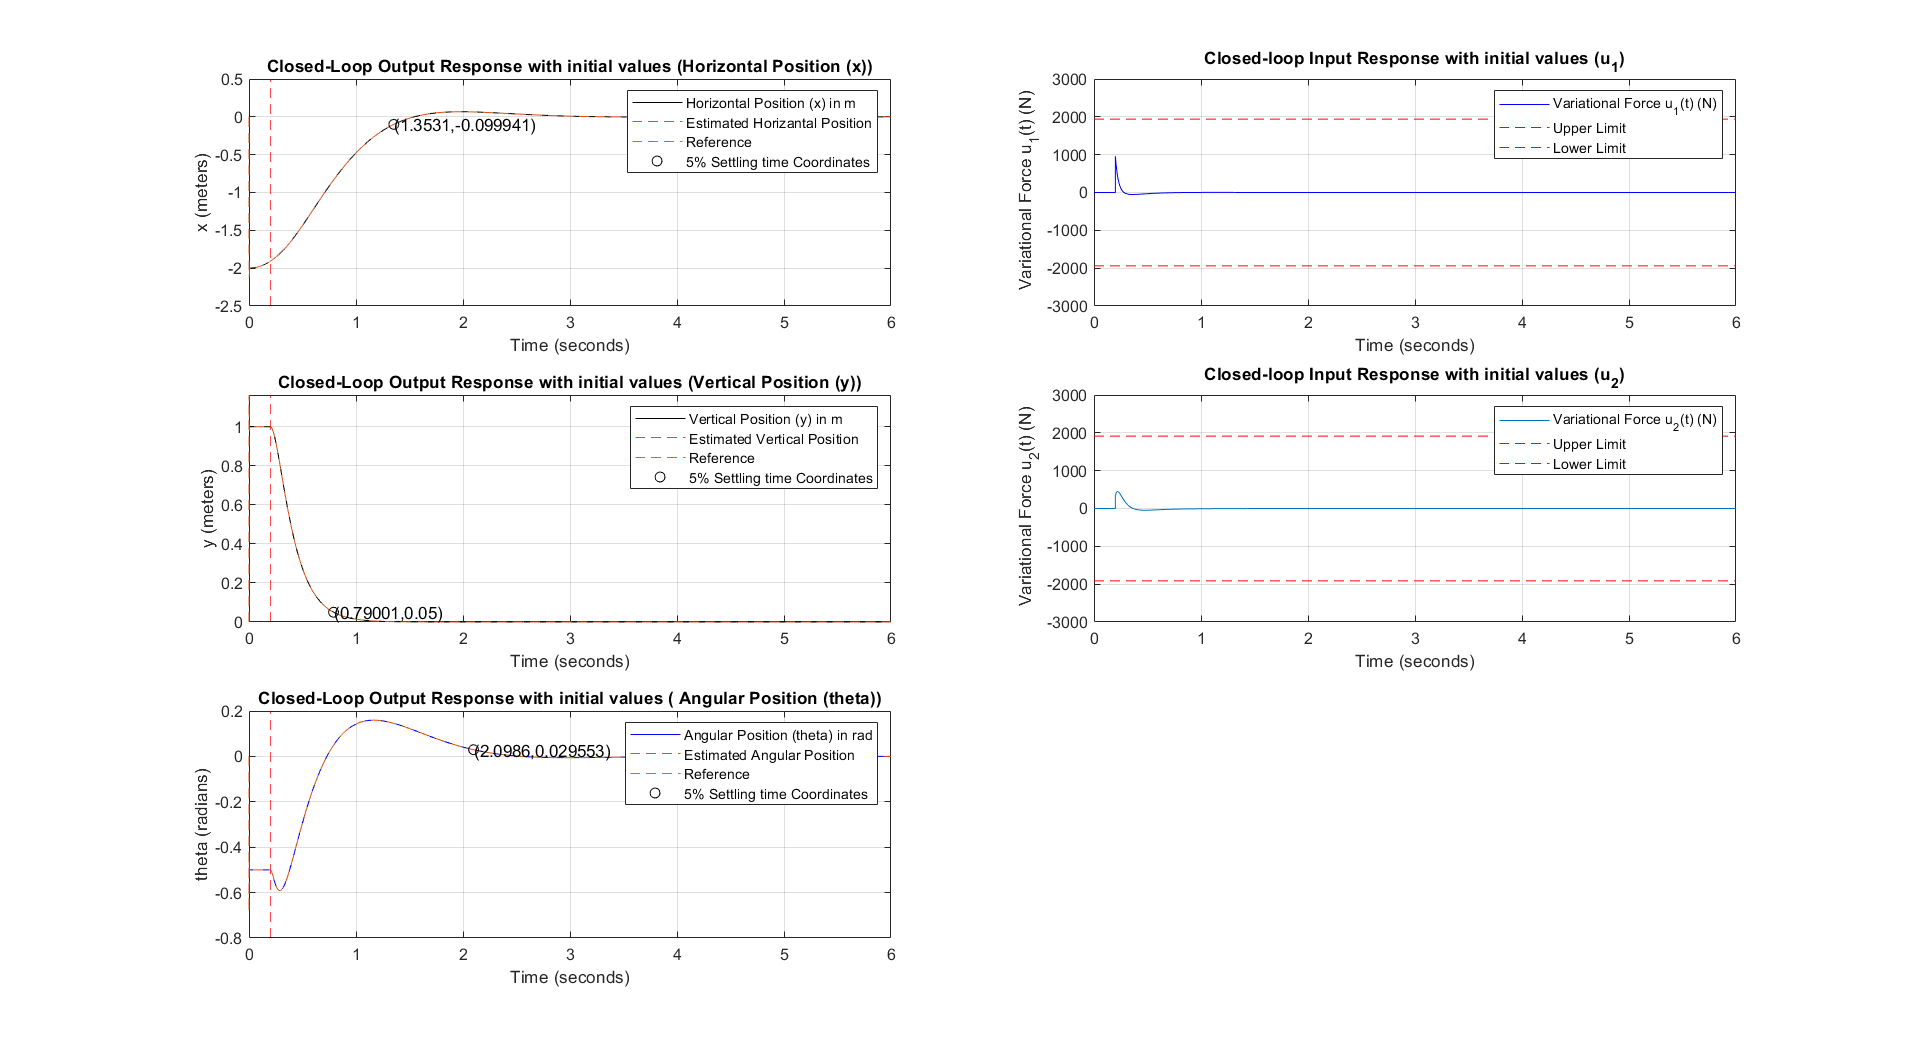


% 5% settling time for Estimated outputs
Estimated_HorizontalPosition_SettlingTime3= lsiminfo(Y_append(:,4),T_append,'SettlingTimeThreshold',0.05);
Estimated_VerticalPosition_SettlingTime3 = lsiminfo(Y_append(:,5),T_append,'SettlingTimeThreshold',0.05);
Estimated_AngularPosition_SettlingTime3 = lsiminfo(Y_append(:,6),T_append,'SettlingTimeThreshold',0.05);


% Plot control signals and outputs  
figure();
% Closed-Loop Output Response with initial values (Horizontal Position (x))
subplot(3,2,1);
plot(T_append,Y_append(:,1),'k');
grid on
hold on
plot(T_append,Y_append(:,4),'--');
%xlim([0 6])
title(['Closed-Loop Output Response with initial values (Horizontal Position (x))']);
xlabel('Time (seconds)')
ylabel('x (meters)')
vRefl=xline(Tfinal_stage1); 
set(vRefl,'color','r','linestyle','--');
plot(YTab2.SettlingTime(1),HorizontalPosition_SettlingTime2,'kO');
text(YTab2.SettlingTime(1), HorizontalPosition_SettlingTime2,['(' num2str(YTab2.SettlingTime(1)) ',' num2str(HorizontalPosition_SettlingTime2) ')']);
legend('Horizontal Position (x) in m','Estimated Horizantal Position','Reference', '5% Settling time Coordinates', '');

%Closed-Loop Output Response with initial values (Vertical Position (y))
subplot(3,2,3);
plot(T_append,Y_append(:,2),'k');
grid on
hold on
plot(T_append,Y_append(:,5),'--');
xlim([0 6])
title(['Closed-Loop Output Response with initial values (Vertical Position (y))']);
xlabel('Time (seconds)')
ylabel('y (meters)')
vRefl=xline(Tfinal_stage1); 
set(vRefl,'color','r','linestyle','--');
plot(YTab2.SettlingTime(2), VerticalPosition_SettlingTime2,'kO');
text(YTab2.SettlingTime(2),VerticalPosition_SettlingTime2,['(' num2str(YTab2.SettlingTime(2)) ',' num2str(VerticalPosition_SettlingTime2) ')']);
legend('Vertical Position (y) in m', 'Estimated Vertical Position','Reference', '5% Settling time Coordinates', '');

%Closed-Loop Output Response with initial values ( Angular Position (theta))
subplot(3,2,5);
plot(T_append,Y_append(:,3),'b');
grid on
hold on
plot(T_append,Y_append(:,6),'--');
title(['Closed-Loop Output Response with initial values ( Angular Position (theta))']);
xlabel('Time (seconds)')
ylabel('theta (radians)')
xlim([0 6])
vRefl=xline(Tfinal_stage1); 
set(vRefl,'color','r','linestyle','--');
plot(YTab2.SettlingTime(3),AngularPosition_SettlingTime2,'kO');
text(YTab2.SettlingTime(3),AngularPosition_SettlingTime2 ,['(' num2str(YTab2.SettlingTime(3)) ',' num2str(AngularPosition_SettlingTime2) ')']);
legend('Angular Position (theta) in rad','Estimated Angular Position','Reference','5% Settling time Coordinates', '');

%Closed-loop Input Response with initial values (u_1)
 subplot(3,2,2); 
 plot(T_append,ControlInput_append(:,1),'b');
 grid on
 hold on
 hRl=refline(0,1939.936);
 set(hRl,'color','r','linestyle','--'); 
 hR2=refline(0,-1939.936);
 set(hR2,'color','r','linestyle','--'); 
 title('Closed-loop Input Response with initial values (u_1)');
 xlabel('Time (seconds)')
 ylabel(' Variational Force u_1(t) (N)')
 ylim([-3e3 3e3])
 xlim([0 6])
 legend('Variational Force u_1(t) (N)','Upper Limit','Lower Limit');
 
% %Closed-loop Input Response with initial values (u_2)
 subplot(3,2,4);
 
 plot(T_append,ControlInput_append(:,2))
 grid on
 hold on
 hRl=refline(0,1912.914);
 set(hRl,'color','r','linestyle','--'); 
 hR2=refline(0,-1912.914);
 set(hR2,'color','r','linestyle','--'); 
 title('Closed-loop Input Response with initial values (u_2)');
 xlabel('Time (seconds)')
 ylabel(' Variational Force u_2(t) (N)')
 ylim([-3e3 3e3])
 xlim([0 6])
 legend('Variational Force u_2(t) (N)','Upper Limit','Lower Limit');
set(gcf, 'Units', 'Normalized', 'Position', [1, 1, 1, 1]);

## **Problem 4a****.  **

Use the LQI function in Matlab to design a feedback gain matrix for state

feedback + integral control to enable the outputs to track reference inputs. Similar to Problem 1, you

will need to choose individual weights for Q and R, but note that Q will also include weights for the

individual error terms associated with the integrators. The weights you choose will probably need to be

different from the weights in 1a.

Once you have designed LQI optimal state feedback gains, separate

out the state feedback gains G0 from the integral feedback gains GI.

 % Problem 4a.


Q_lqi = diag([0.1*1e6 0.1*1e6 19*1e6 0.1*1e6 7.9*1e6 3.1*1e6 9*1e6 9*1e6 50*1e6] );% Q Matrix 
R_lqi = diag([4.5 3.1]);%R Matrix


[K_lqi,S_lqi,E_lqi] = lqi(ol_sys, Q_lqi, R_lqi);% LQI Function


G0 = K_lqi(:,1:6); %  State Feedback gains
GI = K_lqi(:,7:9); %  Integral Feedback gains 

State_Feedback_Gains = G0;
Integral_Feedback_Gains = GI;

## **Problem 4b. **

 Before simulating the closed-loop response of the LQI Feedback control

system with integral control for reference tracking, you must first construct a closed-loop LTI statespace

object. You may choose any one of the three methods defined below.

**Method B**: Implement the LQI feedback control system with an observer. This is a proper output

feedback control system design where the estimated states are used in the control law.

The equations for this system were derived for you and can be found in the notes.

%  Problem 4b.
%Using Method B

A_lqr= [A_ol_sys,     (-B_ol_sys* GI), -B_ol_sys*G0;...
             -C_ol_sys,    D_ol_sys*GI,  D_ol_sys*G0;... 
             K_obsv*C_ol_sys, -B_obsv*GI, A_obsv-K_obsv*C_obsv-B_obsv *G0 ];
B_lqr = [zeros(6,3); eye(3);zeros(6,3)];
C_lqr=[C_ol_sys, zeros(3,3),    -D_ol_sys*G0; zeros(3,6),  zeros(3,3),  C_ol_sys-D_ol_sys*G0 ];

D_lqr = [];

%LQI feedback control system with an observer.
LTI_lqi_sys = ss(A_lqr, B_lqr, C_lqr, D_lqr);



### **Problem 4c:**

**Reason:**

**Requirements:**

• The total simulation time must be 20 seconds or less

• The observer and the controller start at the same time, which is t=0

• The control objective is to land the drone at the position x=2, y=0, without ever allowing any part

of the drone to contact the ground until the end, and the drone must also avoid contacting a

1.5m wall 

• use the observer gains from problem 3 

•  construct a reference profile for the control system to track

• The initial position of the drone must be at x=-2, y=1;

• choose the initial state of the observer to match the initial state of the plant.

• The absolute value of the pitch angle q can never exceed 30 degrees at any point in the

**Simulation Requirements**

• Neither of the control signals can exceed the saturation limits

   $u_{1}< u_{1_{max}}$     and $u_{2}<u_{2_{max}$

• Plot the actual outputs and the estimated outputs on the corresponding axes like you did for problem 3

• You must plot your reference trajectories on the output plots (there is no need for a legend as

long as it is very clear which signal is the reference, which is the actual output, and which is the

estimated output)


%Problem 4c

%Initial states of the observer
State_Vector_0_lqi = [0;0;-0.1745;0;-2;1; -1.5; 0.33; 0; 0;0;-0.1745;0;-2;1]; 


%Reference Profile
%Reference for Horizontal Position 
Tfinal_lqi=20;
 x_reference2= zeros(1,51);
 x_reference4=2*ones(1,101);
 x_reference3=0:0.02:2;
  x_reference1= -2:0.02:0;
 x_reference=[x_reference1, x_reference2, x_reference3, x_reference4];
%Reference for Angular rotation 
theta_reference3 = (pi/180)*(2:(-0.02):0);
theta_reference1 = (pi/180*(-10:0.12:2));
theta_reference4 = zeros(1,101);
theta_reference2 = ones(1,51)*(2*pi/180);

 theta_reference = [theta_reference1, theta_reference2, theta_reference3, theta_reference4];
 %Reference for Vertical Position 
 y_reference5=zeros(1,7);
 y_reference2 = 1:0.02:2;
  y_reference3 = ones(1,101)*2;
 y_reference4 = 2:(-0.02150):0;
 y_reference1 = ones(1,101);
 y_reference = [y_reference1, y_reference2, y_reference3, y_reference4,y_reference5];


TReference=20/353;% TReference
 TReference_lqi=0:(20/353):20;
%Input Reference
 Input_Reference=[x_reference; y_reference; theta_reference];
 
[Y_final_lqi, T_final_lqi, X_final_lqi] = lsim(LTI_lqi_sys,Input_Reference,TReference_lqi, State_Vector_0_lqi);


Y_Output_lqi = lsiminfo(Y_final_lqi,T_final_lqi,'SettlingTime',0.05);

% Converting LSIMINFO structure to a table for display purposes
YTable4 = struct2table(Y_Output_lqi); 

% Horizontal Position (m) of the CG in the world coordinate system at 5% Settling time, 
HorizontalPosition_SettlingTime5 = interp1(T_final_lqi(:,1),Y_final_lqi(:,1),YTable4.SettlingTime(1));
disp(' Horizontal Position (x) at 5% Settling time: ');

 Horizontal Position (x) at 5% Settling time: 


fprintf('Time = %.4f s, HorizontalPosition(x) = %.4f m', YTable4.SettlingTime(1), HorizontalPosition_SettlingTime5);

Time = 15.4752 s, HorizontalPosition(x) = 1.7987 m

% Vertical Position (m) of the CG in the world coordinate system at 5% Settling time,
VerticalPosition_SettlingTime5 = interp1(T_final_lqi(:,1),Y_final_lqi(:,2),YTable4.SettlingTime(2));
disp(' VerticalPosition (y) at 5% Settling time: ');

 VerticalPosition (y) at 5% Settling time: 


fprintf('Time = %.4f s, VerticalPosition (y) = %.4f m', YTable4.SettlingTime(2), VerticalPosition_SettlingTime5);

Time = 19.7231 s, VerticalPosition (y) = 0.2594 m


% Angular position (rad) of the open-top bin at 5% Settling time
AngularPosition_SettlingTime5 = interp1(T_final_lqi(:,1),Y_final_lqi(:,3),YTable4.SettlingTime(3));
disp('Angular position (theta) at 5% Settling time: ');

Angular position (theta) at 5% Settling time: 


fprintf('Time = %.4f s, AngularPosition(theta) = %.4f rad', YTable4.SettlingTime(3), AngularPosition_SettlingTime5);

Time = 3.3674 s, AngularPosition(theta) = -0.0336 rad

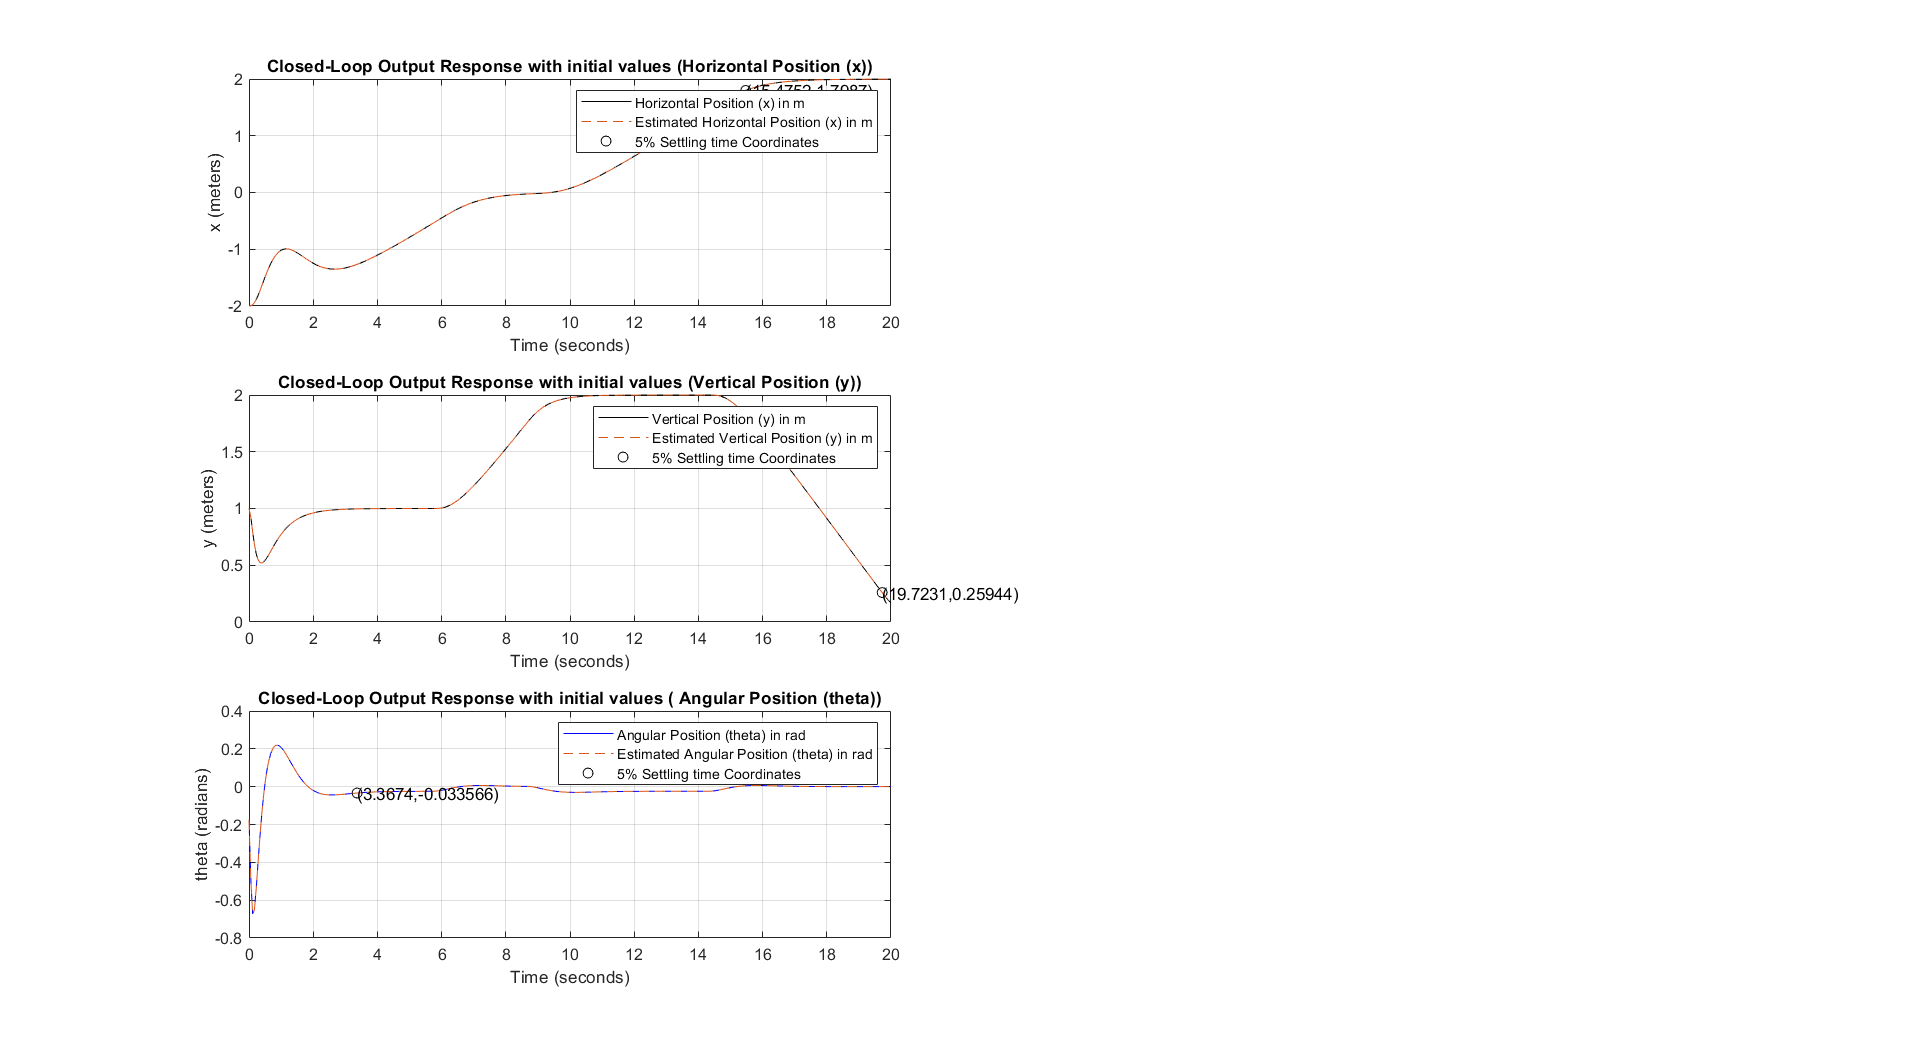



% Plot control signals and outputs  
figure();
% Closed-Loop Output Response with initial values (Horizontal Position (x))
subplot(3,2,1);
plot(T_final_lqi,Y_final_lqi(:,1),'k');
grid on
hold on
plot(T_final_lqi,Y_final_lqi(:,4),'--');
%xlim([0 6])
title(['Closed-Loop Output Response with initial values (Horizontal Position (x))']);
xlabel('Time (seconds)')
ylabel('x (meters)')

plot(YTable4.SettlingTime(1),HorizontalPosition_SettlingTime5,'kO');
text(YTable4.SettlingTime(1), HorizontalPosition_SettlingTime5,['(' num2str(YTable4.SettlingTime(1)) ',' num2str(HorizontalPosition_SettlingTime5) ')']);
legend('Horizontal Position (x) in m', 'Estimated Horizontal Position (x) in m', '5% Settling time Coordinates', '');

%Closed-Loop Output Response with initial values (Vertical Position (y))
subplot(3,2,3);
plot(T_final_lqi,Y_final_lqi(:,2),'k');
grid on
hold on
plot(T_final_lqi,Y_final_lqi(:,5),'--');
%xlim([0 6])
title(['Closed-Loop Output Response with initial values (Vertical Position (y))']);
xlabel('Time (seconds)')
ylabel('y (meters)')
plot(YTable4.SettlingTime(2), VerticalPosition_SettlingTime5,'kO');
text(YTable4.SettlingTime(2),VerticalPosition_SettlingTime5,['(' num2str(YTable4.SettlingTime(2)) ',' num2str(VerticalPosition_SettlingTime5) ')']);
legend('Vertical Position (y) in m', 'Estimated Vertical Position (y) in m', '5% Settling time Coordinates', '');

%Closed-Loop Output Response with initial values ( Angular Position (theta))
subplot(3,2,5);
plot(T_final_lqi,Y_final_lqi(:,3),'b');
grid on
hold on
plot(T_final_lqi,Y_final_lqi(:,6),'--');
title(['Closed-Loop Output Response with initial values ( Angular Position (theta))']);
xlabel('Time (seconds)')
ylabel('theta (radians)')
%xlim([0 6])

plot(YTable4.SettlingTime(3),AngularPosition_SettlingTime5,'kO');
text(YTable4.SettlingTime(3),AngularPosition_SettlingTime5 ,['(' num2str(YTable4.SettlingTime(3)) ',' num2str(AngularPosition_SettlingTime5) ')']);
legend('Angular Position (theta) in rad','Estimated Angular Position (theta) in rad','5% Settling time Coordinates', '');

set(gcf, 'Units', 'Normalized', 'Position', [1, 1, 1, 1]);

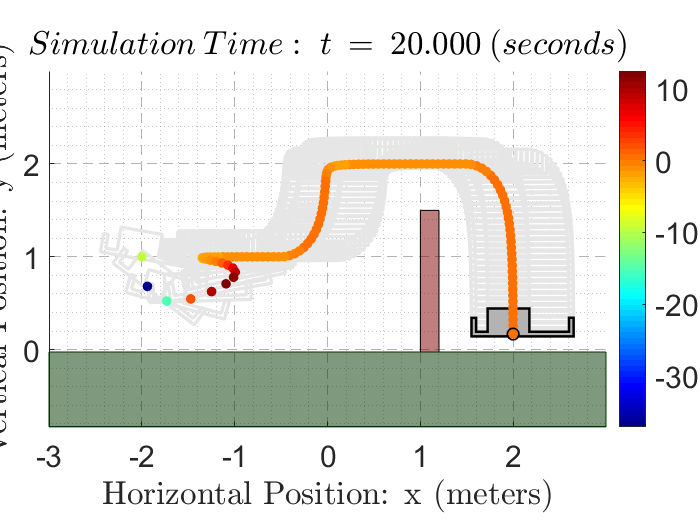

als_f20_animate(T_final_lqi,Y_final_lqi(:,1),Y_final_lqi(:,2),Y_final_lqi(:,3));